# Furuta Pendulum - Controller Comparison

## 1. Load the Three Results

Use the results produced by the three controller Live Scripts. Run PID, Pole Placement and LQR first. These are the results of the current tests, not separate historical runs.

assert(isfolder('data') && isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
PID_result = load('results/PID_Result.mat');
PP_result = load('results/PP_Result.mat');
LQR_result = load('results/LQR_Result.mat');
results = {PID_result,PP_result,LQR_result};
names = {'PID + pendulum PD','Pole Placement','LQR'};


## 2. Check a Fair Comparison

Before comparing results, check that the pulse, run time, torque limit and linear plant model are the same.

for k = 2:3
    assert(isequal(results{1}.test,results{k}.test),'Different disturbance tests.');
    assert(isequal(results{1}.A,results{k}.A) && isequal(results{1}.B,results{k}.B), ...
        'Different plant models: rerun all three controllers.');
end
figure('Name','Three-controller comparison','Color','w'); tiledlayout(2,2);


## 3. Pendulum Response

Compare the peak pendulum angle and the time needed to return near upright.

nexttile; hold on;
for k = 1:3, plot(results{k}.t,rad2deg(results{k}.x(:,2))); end
grid on; ylabel('Pendulum (deg)'); xlabel('Time (s)'); legend(names,'Location','best');


## 4. Arm Response

Fast pendulum recovery does not always mean fast arm recovery. Show the two angles separately.

nexttile; hold on;
for k = 1:3, plot(results{k}.t,rad2deg(results{k}.x(:,1))); end
grid on; ylabel('Arm (deg)'); xlabel('Time (s)');


## 5. Control Effort and Velocity

Compare actuator torque and pendulum velocity. Use the same units and time axis for all curves.

nexttile; hold on;
for k = 1:3, plot(results{k}.t,results{k}.u); end
grid on; ylabel('Actuator torque (N m)'); xlabel('Time (s)');
nexttile; hold on;
for k = 1:3, plot(results{k}.t,results{k}.x(:,4)); end
grid on; ylabel('Pendulum velocity (rad/s)'); xlabel('Time (s)');
sgtitle('Same plant and disturbance | PID vs Pole Placement vs LQR');


## 6. Performance Table

The table shows peaks, settling times, IAE, control effort and saturation from the same tests. Percentage overshoot needs a clear definition when the reference is zero.

comparison_table = [PID_result.performance;PP_result.performance;LQR_result.performance];
comparison_table.Properties.RowNames = names;
comparison_table

comparison_table = 3×8 table
                         PeakPendulum_deg    PeakArm_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    RmsTorque_Nm    PendulumIAE_rad_s    SaturationFraction
                         ________________    ___________    __________________    _____________    _____________    ____________    _________________    __________________

    PID + pendulum PD         2.7646           16.123             0.934               6.907          0.0092042       0.00068544         0.015344                 0         
    Pole Placement            3.0541           18.427             1.307               1.338          0.0088045       0.00069794         0.017122    

writetable(comparison_table,'results/Controller_Comparison.csv','WriteRowNames',true);


## 7. Discussion and Save

With the current gains, PID returns the pendulum faster but the arm more slowly. LQR gives a lower pendulum peak and IAE in this test. Pole Placement returns the arm quickly. No controller is best on every measure. One test does not prove global stability.

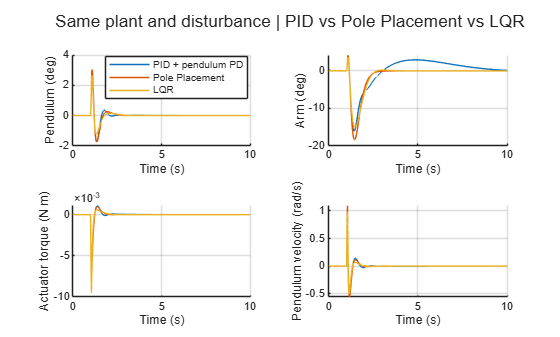

drawnow; exportgraphics(gcf,'results/Controller_Comparison.png','Resolution',140);

save('results/Controller_Comparison.mat','comparison_table');
